clc;clear

% g=-8:0.1:-3.99;
g=-6

g = -6

rrr=zeros(size(g,2),2);

for i=1:size(g,2)
    G=g(i);
    rho0=1;
    cs2=1/3;

    % rho=0:0.01:5;
    % equation1= SCEOS(rho,G);

    % subplot(2,1,1)
    % plot(rho,equation1)
    % xlabel('rho')
    % ylabel('P')
    % subplot(2,1,2)
    % plot(1./rho,equation1)
    % 
    % xlabel('nu')
    % ylabel('P')
    % box on


    % 定义符号变量
    syms rho;

    % 定义状态方程
    equation1 = cs2*rho + cs2*G/2*(rho0*(1-exp(-rho/rho0))).^2;

    % 对rho求导
    derivative = diff(equation1, rho);

    % 解导数等于零的方程
    critical_points = solve(derivative == 0, rho);

    % 将符号解转换为数值解
    rho_values = sort(double(critical_points));
    rholeft=rho_values(1);
    rhoright=rho_values(2);
    % 输出极值点
    % disp('极值点 rho:');
    % disp(rho_values);

    pMaxAndMin=SCEOS(rho_values,G);
    pleft=pMaxAndMin(1);
    pright=pMaxAndMin(2);


    pmax=pleft;
    pmin=pright;
    for j=1:30
        ptemp=(pmax+pmin)/2;

        EOS=@(rho) ptemp-cs2*rho - cs2*G/2*(rho0*(1-exp(-rho/rho0))).^2;
        rhog=fzero(EOS,[-1,rholeft]);
        rhol=fzero(EOS,[rhoright,20]);


        F_EOS=@(rho) (ptemp-(cs2*rho + cs2*G/2*(rho0*(1-exp(-rho/rho0))).^2)).*exp(-rho/rho0)./(rho0*(1-exp(-rho/rho0))).^2;
        F=integral(F_EOS,rhog,rhol);

        if F>0
            pmax=ptemp;
        else
            pmin=ptemp;
        end
    end

    rrr(i,1)=rhog;
    rrr(i,2)=rhol;
end

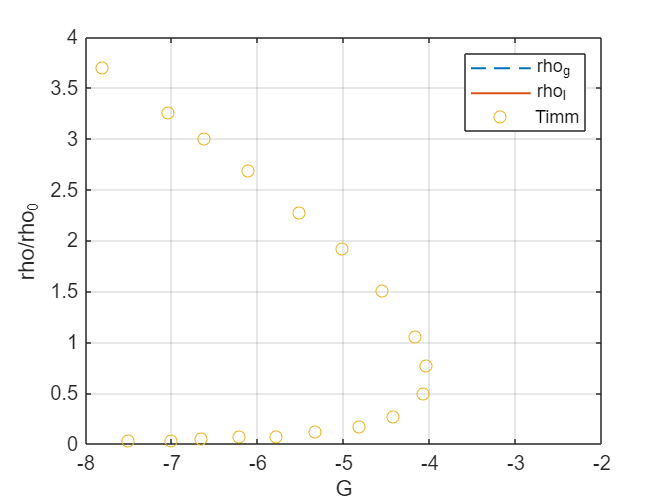



hold on
plot(g,rrr(:,1),LineWidth=1,LineStyle="--")
plot(g,rrr(:,2),LineWidth=1)

data=[-7.009061075131415, 0.030479481892370153
-7.042865855429385, 3.2630325559782767
-7.51012110475416, 0.0328318763976414
-6.656724653675253, 0.049952080852670555
-6.217785264136149, 0.0690180931083555
-5.7848575494438474, 0.07402782214735826
-5.3338948102111345, 0.12120640083640666
-4.814974007492812, 0.175108181105335
-4.420294484941771, 0.2718467748961748
-4.070484709435716, 0.49555658815670967
-7.8029506577992045, 3.7032207475386985
-6.618999215868499, 3.0004791914732962
-6.114105654459386, 2.6882496442366333
-5.5213893648534835, 2.277016234426277
-5.022158975401505, 1.9225597537246246
-4.553074085905963, 1.5048645195016408
-4.170156535881277, 1.0523625591728862
-4.036767054860163, 0.7700461766328806
];

scatter(data(:,1),data(:,2))
legend('rho_g',"rho_l","Timm")
xlim([-8,-2])
box on ;grid on
xlabel("G")
ylabel("rho/rho_0")